P1 =[0 0];
P2=[0.05 0.5];
P3=[0.05 1.5];
P4=[0 2];
P5=[0.06 0];
P6=[0.1 0.25];
P7=[0.1 0.75];
P8=[0.1 1];
P9=[.6 1];
P10=[.6 2];
P11=[0.1 1.2];
P12=[0.5 1.2];
P13=[0.5 1.8];
P14=[0.08 1.8];

P1 = transfopoint(P1);
P2 = transfopoint(P2);
P3 = transfopoint(P3);
P4 = transfopoint(P4);
P5 = transfopoint(P5);
P6 = transfopoint(P6);
P7 = transfopoint(P7);
P8 = transfopoint(P8);
P9 = transfopoint(P9);
P10 = transfopoint(P10);
P11 = transfopoint(P11);
P12 = transfopoint(P12);
P13 = transfopoint(P13);
P14 = transfopoint(P14);


hold on

t = 0:0.01:1

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900



% window(P1, P4, P10, P9)

[x, y]= xy(P1, P2, P3, P4);

x =          0    0.4830    1.3490    1.7321


y =          0    0.5000    1.5000    2.0000


plot(x,y , 'o');
[x, y] = xy(P4, P5, P6, P7);

x =     1.7321    0.0600    0.3165    0.7495


y =     2.0000         0    0.2500    0.7500


plot(x,y , 'o');
[x,y] = xy(P8, P9, P10, P11);

x =     0.9660    1.4660    2.3321    1.1392


y =     1.0000    1.0000    2.0000    1.2000


plot(x,y , 'o');
[x,y] = xy(P12, P13, P14, P14);

x =     1.5392    2.0588    1.6388    1.6388


y =     1.2000    1.8000    1.8000    1.8000


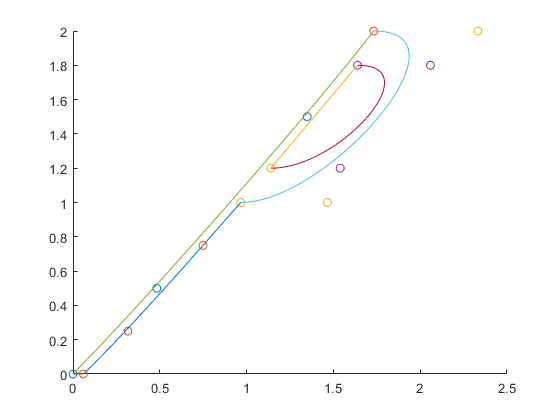

plot(x,y , 'o');


M = bezier4(P1, P2, P3, P4, t);
plot(M(:,1), M(:,2));

M = bezier4(P4, P10, P9, P8, t);
plot(M(:,1), M(:,2));

M = bezier4(P14, P13, P12, P11, t);
plot(M(:,1), M(:,2));

M = bezier4(P8, P7, P6, P5, t);
plot(M(:,1), M(:,2));

plot([P1(1), P5(1)], [P1(2), P5(2)]);
plot([P14(1), P11(1)], [P14(2), P11(2)]);